# Parameter Estimation of the DFN Model 

In this example, we explore the parameter estimation method which was developed in [Khalik et. al. JPS 2021]. Note that this same parameter estimation script also works for the work of [le Roux et. al., IFAC, 2023] . The basic description of the inputs and outputs of the parameter determination method are as follows:

[p, ph, results] = parameter_determination(equil_data,est_data,options_in)

where

- p: contains the estimated DFN model parameters.

- ph: contains the estimated reformulated DFN model parameters (see [2] for more details on the reformulated DFN model).

- results: contains additional information on the estimation results.

- equil_data is a struct that contains the information on the equilibrium potential of the cell (or the EMF). When the EMF is used, there should be 2 fields in equil: EMF and Cbat. EMF should be function of SOC and Cbat should be given in C. 

- est_data is a cell that can contain multiple structs that in itself contain the measurement data. In each of the structs, there should be at least 3 fields: t, I, V. t is the time vector, I contains the applied current measurements and V the terminal voltage measurements. For simplicity, make sure that you interpolate the data such that the sample time is 1 s (see the example data).

- options: specify additional options for the parameter estimation routine.

In the examples below, we will illustrate how to use some basic aspects of the parameter determination method. 

Before we use the script, we first add the main TOOFAB folder to our filepath, such that we can run the example without requiring an independent copy of DFN.m or paraneter_determination.m in our current working folder. 

addpath('../..')

## Example 1: Parameter Estimation of the DFN model using input/output data

In this example, we provide some basic steps on how to use the parameter estimation method provided in this toolbox. We will present this in 3 steps, corresponding to the input parameters of the method.

### Step 1: Electrode Potential Curves. 

The parameter estimation method requires information on the equilibrium potentials of the cell. We typically use an Open-Circuit-Voltage (OCV) curve to illustrate the relationship between open-circuit potential and State-of-Charge (SoC) of the cell. We performed a pulse-discharge test to determine this OCV-SoC relationship. 

First we plot the pulse discharge data as an example,

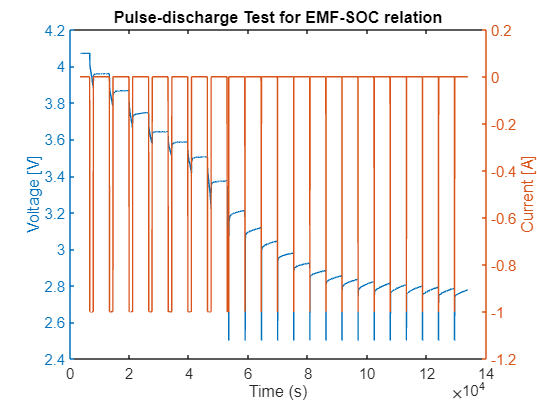

load pulse_discharge.mat
figure;
yyaxis left
plot(Voltage);
ylabel('Voltage [V]')
xlabel("Time (s)");
title('Pulse-discharge Test for EMF-SOC relation');
hold on;
yyaxis right
plot(Current);
ylabel("Current [A]");

From this data, we can identify the relaxation points at the end of each relaxation period of the pulse-discharge test. We first identify the index of the end of the relaxation curve, and then extract the voltage at these points.

points=[]


points =

     []



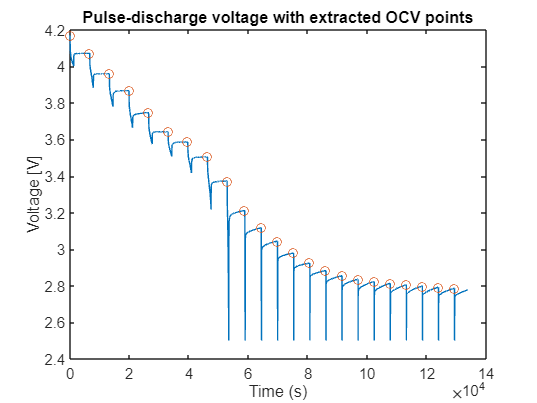

count=1;
for i =1:length(Current)-1
    if Current(i+1)<-0.5 && Current(i)>-0.5
        points(count)=i;
        count=count+1;
    end
end
v_emf=Voltage(points);
figure;
plot(Voltage);
ylabel('Voltage [V]')
xlabel("Time (s)");
title('Pulse-discharge voltage with extracted OCV points');
hold on;
scatter(points,v_emf);

We also need to find the SoC related to these open-circuit voltage points. To calculate the SoC over the pulse-discharge test, we use the coulomb counting method

capacity=-1*cumtrapz(Current); %considering our timestamp is 1s
Cap=capacity(end);
soc = 1-capacity/capacity(end);
soc_emf = soc(points);


We can now construct a griddedinterpolant object which will represent our OCV-SoC relation:

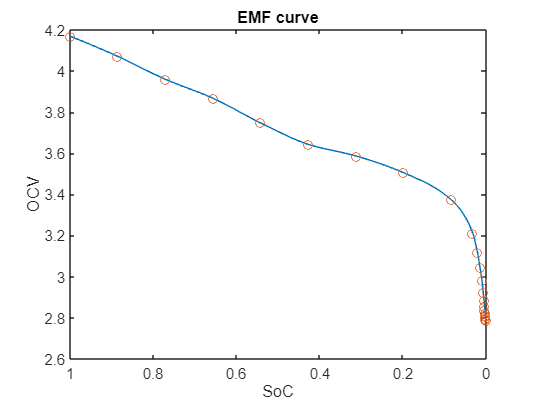

EMF=griddedInterpolant(flip(soc_emf),flip(v_emf),'pchip');
figure;
plot(0:0.01:1,EMF(0:0.01:1)); hold on; scatter(soc_emf,v_emf);set(gca, 'XDir', 'reverse')
xlabel('SoC'); ylabel('OCV');
title('EMF curve')

The EMF griddedinterpolant object, along with the cell capacity (in As), labeled 'Cbat', is provided to the parameter estimation procedure in the form of a structure, which we refer to as equil. 

equil.Cbat = capacity(end);
equil.EMF=EMF;

### Step 2: Input/Output Data

The estimation data consists of a Time, Current and Voltage array, such that the least squares optimisation problem can minimise the sum of squared error between the predicted and measured voltage output. The V,I and t arrays should each be [1xN] where N refers to the length of the experiment. The timestamp used in these examples is 1s. It is important that the first time value is 1 and not 0, otherwise the model will fail. 

load Estimation.mat

This loads the `data` struct (fields `t`, `I`, `V`) used below. 

### Step 3: Options

There are some options which the user can set based on preferences related to the parameter estimation procedure. 

The most commonly-needed options are the ambient temperature at which the experiment took place (options.dfn.T_amb), and the number of parameters to estimate (options.n_estimation). Setting options.n_estimation limits estimation to the first N parameters (in the order listed internally), holding the rest at their nominal, mid-range value - useful for a quicker run when not every parameter needs fitting. Other DFN model settings (e.g. set_simp, the model-simplification level) can be overridden the same way, under options.dfn, if needed - see parameter_determination.m's header for the default values.

options.n_estimation=28;
options.dfn.T_amb=273.15+22;

### Step 4: Run the Parameter estimation procedure

Now that our inputs have been correctly defined, we can run the parameter estimation procedure!

[Out.p, Out.ph, Out.results] = parameter_determination(equil,data,options);

11:36:30 Performing the parameter estimation procedure...
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.

                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0         29            3860.5                         4.11e+03
     1         58            3860.5         1.01054         4.11e+03      
     2         87           1168.21        0.285019              391      
     3        116           1028.35        0.505269              384      
     4        145           496.416        0.931301         1.04e+03      
     5        174           496.416         1.07077         1.04e+03      
     6        203           496.416        0.267692         1.04e+03      
     7        232           496.416       0.0669231         1.04e+03      
     8        261           496.416       0.0167308         1.04e+03      
     9        290      

Out.p contains the full (ungrouped) parameter set, Out.ph contains the estimated values of the grouped parameter set. Out.results contains information about the estimation procedure. 

fval is the final residual value of the estimation procedure, est_time is the time it took for the parameter estimation procedure to complete. beta_est are the estimated beta values on the scale of [0,1] and beta_0 is the initial conditions of each parameter. Finally, lsqnonlin_output contains the outputs of the lsqnonlin function used in the parameter estimation procedure. 

### Step 5: Validate the estimated parameter set

Once the model parameters have been estimated, we can validate the parameters using a true validation dataset, i.e., an experimental data set where the current profile is entirely different to the estimation current profile. 

load Validation.mat
p=Out.p; ph=Out.ph;
val_Out=DFN([t' Current'],t(end),Voltage(1),p);

Plotting the model output which simulated using the estimated parameter set, on the validation dataset. 

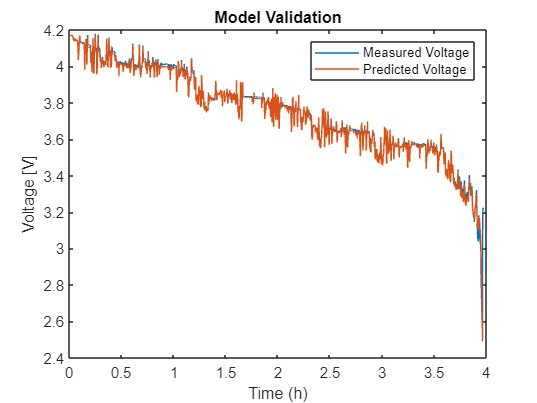

figure;
plot(t/3600,Voltage,val_Out.t/3600,val_Out.V);
xlabel("Time (h)"); ylabel("Voltage [V]"); legend("Measured Voltage", "Predicted Voltage");
title("Model Validation");

### Step 6: Accessing the parameters and further information

The Out struct contains three fields. results is the output from the lsqnonlin solver. The includes fval, the final evaluation output (i.e., the residual at which the optimisation procedure stopped), est_time is the time it took for the optimisation to complete, beta_0 is the initial condition for the parameter set and beta_est is the estimated scaled parameter values on the range of [0 1].  ph, is the list of grouped parameters estimated in the parameter estimation procedure. p, is the full DFN parameter set, extracted from the function 'phat2p' in the parameter_determination.m script.

The parameter ranges used in this example are a set of predefined ranges. These can be changed to match a preferred cell chemistry, and can be done in the determine_parameter_ranges function in the parameter_deremination.m script. A detailed description of this subfunction, and all other functions of the parameter estimation method can be found in the user manual. 